%Fecha de actualización: 23/oct/2023
%V 0.1.1
%clc
%clear all

# Practica 006: Curso de MATLAB para ingeniería

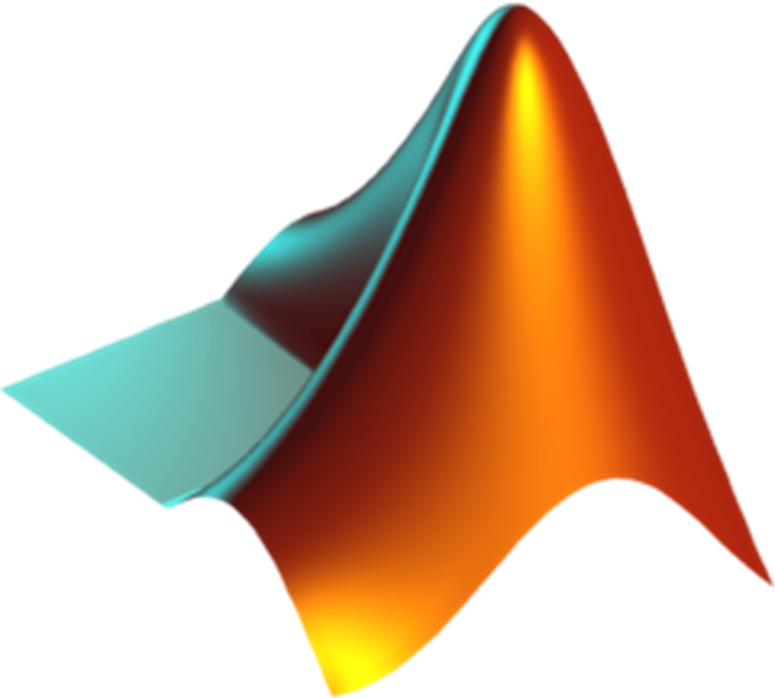

## Manejo de archivos de Bases de Datos

Un modelo de datos o DataFrame es una estructura de datos tabular, la cual organiza la información en filas y columnas de manera similar a una hoja de cálculo. En particular cada columna del DataFrame representa una variable o feature (atributo), mientras que cada fila representa una observación o registro realizado. Los DataFrames son utilizados comúnmente en análisis de datos para manipular y analizar grandes conjuntos de datos de forma eficiente. Existen diversos métodos de almacenar esta informacion dependiendo del lenguaje de programacion utilizado. El formato universal y más tradicional de almacenamiento de la informacion es mediante archivos de tipo CSV. Un archivo de formato CSV es en realidad un archivo en formato de codificacion de texto plano, donde cada línea del archivo representa una fila de datos, y los valores de cada columna están separados por un carácter delimitador, siendo generalmente este una coma. Es un formato popular debido a su simplicidad y fácil manipulación por programas y hojas de cálculo. Además, muchos sistemas y aplicaciones pueden exportar datos en formato CSV, lo que lo hace fácilmente intercambiable entre diferentes plataformas y herramientas. En particular un archivo de tipo CSV se visualiza de la siguiente manera:

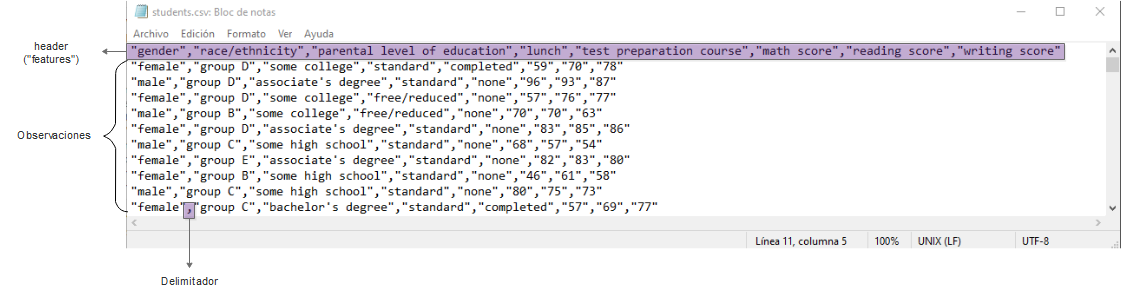

**Figura 1.-** Archivo de tipo CSV visualizado como texto plano

Existen otros formatos de archivos como el parquet, el cual es un formato de archivo de almacenamiento de datos de código abierto utilizado para almacenar datos tabulares en una estructura de columna, en lugar de una estructura de fila tradicional. Este formato está diseñado para ser eficiente en términos de almacenamiento y procesamiento, y permite una lectura y escritura más rápida de grandes conjuntos de datos. En particular, al estar los datos encriptados y codificados en este tipo de archivos, no es posible visualizarlos de manera tradicional, aunque el esquema de organizacion de la información seria lo más cercano a este:

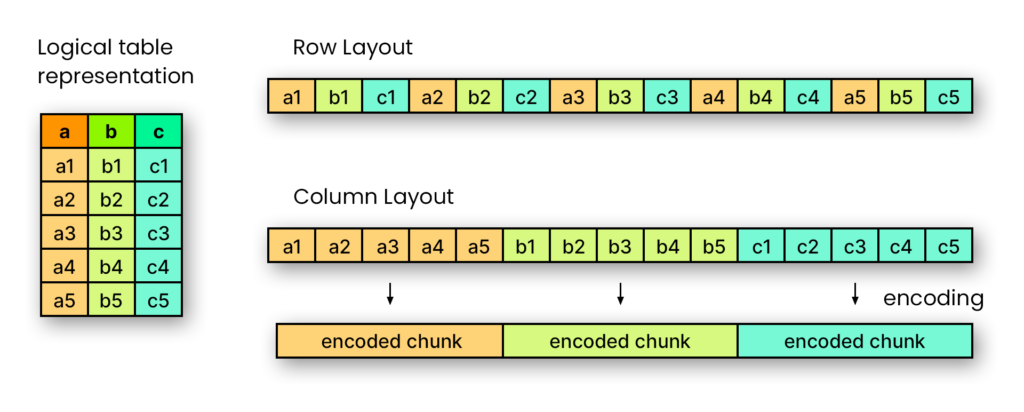

**Figura 2.-** Esquema tradicional de codificacion tipo parquet

Finalmente, el uso y manejo de modelos de datos en MATLAB se realiza mediante la funcion "Datastore". Esta es una función que proporciona una interfaz rápida para acceder a grandes conjuntos de datos, como archivos de imágenes, archivos de audio o archivos de texto, sin cargarlos en la memoria. Permite la lectura de datos de manera eficiente y escalable, ya que lee y procesa los datos de forma incremental a medida que se necesitan, lo que permite trabajar con grandes conjuntos de datos sin tener que cargarlos por completo en la memoria. Además, la función "datastore" permite realizar operaciones de preprocesamiento y manipulación de datos, como filtrado y transformación de datos, de manera eficiente y fácil. Estas bases de datos tienen la siguiente estructura de informacion 

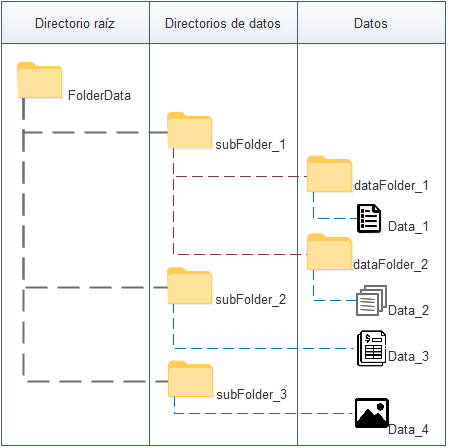

**Figura 3.-** Esquema de un modelo de datos

### Pasos iniciales

%%%
%Creacion de directorio de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='D:\MATLAB_Drive_esc\TSISB_IA';
workingFolder = 'practica_2';
tempFolder = 'temp';
savePath = fullfile(rootFolder,workingFolder);
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);

prefix = ['\' 'students'];
sufix = '.csv';
newName = [prefix, sufix];

%Despues de correr esta celda una vez, crea un bloque de comentarios a partir de esta linea

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

%%%
%Organizacion y copia de archivos
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end
%}

### Modelo de datos mediante un solo archivo

Para lograr el manejo de grandes conjuntos de información, es necesario establecer un "pipeline" o flujo de trabajo de la función datastore. Este se muestra a continuación:

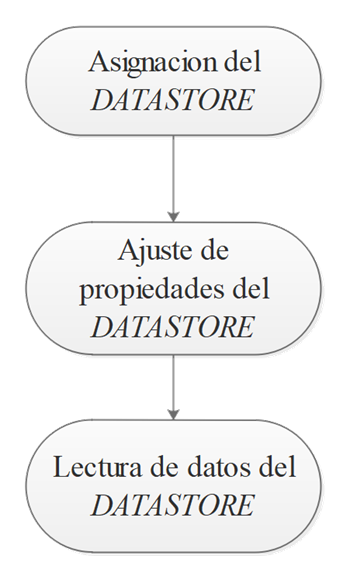

**Figura 2.-** Flujo de trabajo de un Datastore

La primer parte del pipeline del datastore incluye operaciones como:

- Detección de propiedades de los archivos del dataframe/modelo de datos

- Normalizacion de datos

%****
%En este ejercicio solo estaremos trabajando con un archivo
%contenido dentro del datastore
%****

%Se determina la direccion de los archivos que integran el "Datastore"
archivoCSV = [saveTempPath, newName];

%Visualización rápida de las primeras lineas del archivo de texto
%Como solo es un archivo se puede utilizar el comando dbtype
%dbtype(archivoCSV,'10:15')

%Asignamos nuestro datastore dentro de MATLAB
dsGeneral = datastore(archivoCSV)
%Si tuvieramos muchos archivos, se utilizaria el siguiente comando
preview(dsGeneral) 

%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
dsGeneral.VariableNamingRule='preserve'

%Selección del delimitador de texto
dsGeneral.Delimiter=",";

%Modificacion de los nombres utilizados para cada caracteristica/feature
values=dsGeneral.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues=["hola", "esta", "es", "una", "prueba", "de", "cambio", "de etiquetas de columna"];
dsGeneral.VariableNames = newValues;
preview(dsGeneral)

#### Detección y modificación de propiedades de los datos contenidos en el archivo

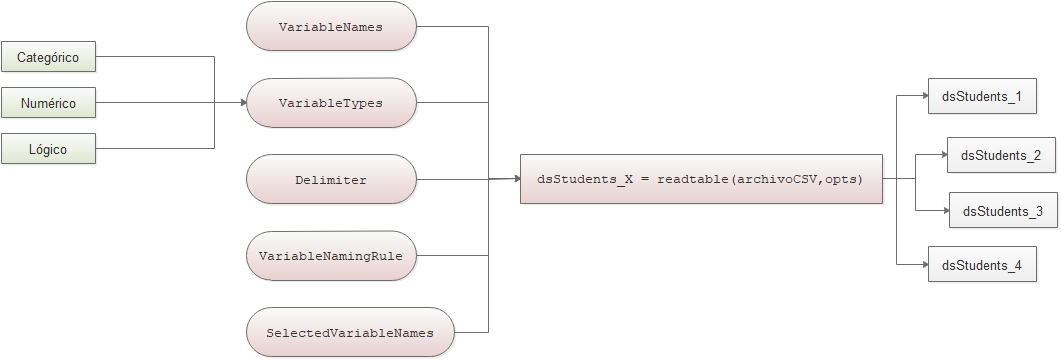

**Figura 3.- **Propiedades de un **datastore de tipo categorico-numérico**

%Visualizacion general de las opciones de importacion de los archivos
%dentro del datastore
opts = detectImportOptions(archivoCSV)

%Visualizacion de los nombres y tipo de variables de las columnas
disp([opts.VariableNames' opts.VariableTypes'])

%Modificacion del tipo de variables 
opts = setvaropts(opts,{'race_ethnicity','gender','parentalLevelOfEducation','lunch','testPreparationCourse'},'Type','categorical');
disp([opts.VariableNames' opts.VariableTypes'])

%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
opts.VariableNamingRule='preserve';

%Selección del delimitador de texto
opts.Delimiter =',';

%Modificacion de los nombres utilizados para cada caracteristica/feature
%Asignacion a una variable particular
values=opts.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues={'hola', 'esta', 'es', 'una', 'prueba', 'de', 'cambio', 'de variables'};
opts.VariableNames = newValues;
dsStudents_1 = readtable(archivoCSV,opts);
head(dsStudents_1)
%regresamos los valores originales
opts.VariableNames = values;
dsStudents_2 = readtable(archivoCSV,opts);
head(dsStudents_2)

%Podemos elegir con que caracteristicas queremos trabajar nuestra base de datos
opts.SelectedVariableNames = {'gender','mathScore','readingScore', 'writingScore'};
dsStudents_3 = readtable(archivoCSV,opts);
head(dsStudents_3)

%y crear distintos tipos de tablas a partir del datastore original
opts.SelectedVariableNames = {'race_ethnicity','mathScore','readingScore', 'writingScore'};
dsStudents_4 = readtable(archivoCSV,opts);
head(dsStudents_4)

### Visualizaciones exploratorias de datos

En este momento se han creado 4 tablas que contienen los siguientes datos

- Tabla 1: No la usaremos

- Tabla 2: Todas las categorias de datos

- Tabla 3: Datos categóricos de genero y datos numéricos de las pruebas de matemáticas, lectura y escritura

- Tabla 4: Datos categóricos de raza etnica y datos numéricos de las pruebas de matemáticas, lectura y escritura

Vamos a realizar un análisis exploratorio de los datos, primero visualicemos un resumen de los datos categoricos contenidos en la tabla 2

### Resumen de datos categoricos

genero = categorical(dsStudents_2.gender);
grpCatGenero = categories(genero)
numCatGenero = countcats(genero)
summary(genero)


etnia = categorical(dsStudents_2.race_ethnicity);
grpCatEtn = categories(etnia)
numCatEtn = countcats(etnia)

%Vamos a reemplazar las categorias origniales por otros nombres
nuevasEtnias = {'Latino',...
                'Afroamericano',...
                'Americano',...
                'Asiatico',...
                'Europeo'};
nuevaEtnia = renamecats(etnia,nuevasEtnias);
summary(etnia)
summary(nuevaEtnia)


#### *** Ejercicio ***

Deberás mostrar cuantas categorias existen en:

- el nivel de educacion de los padres

- si contaron con un desayuno o no

- si hubo una preparacion previa a la prueba

Además deberas de cambiar el nombre de las categorias en la columna "preparacion de la prueba" de la siguiente manera

- completed - > terminado

- none -> no terminado

### Resumen de datos numericos

Ahora vamos a realizar un resumen de los datos numéricos, lo cual puede incluir encontrar la media de los datos de pruebas numericas

Los distintos tipos de operaciones numéricas que podemos realizar son las siguientes

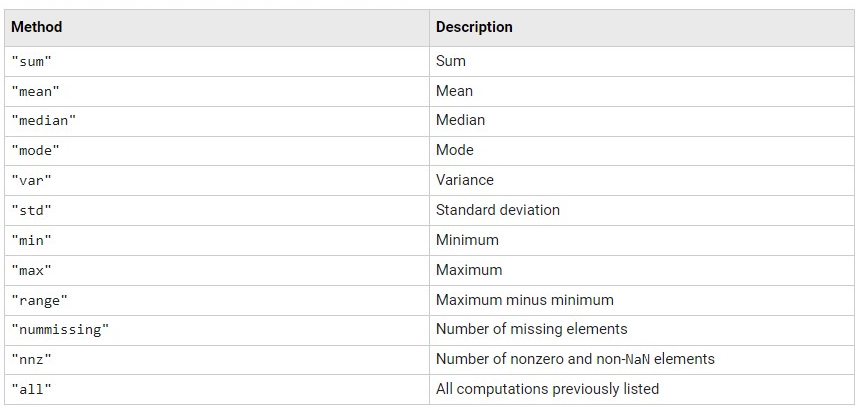

**Figura 4.-** Operaciones numéricas de una tabla

%Primero veremos el score promedio dependiendo del genero, utilizando la
%tabla 3
genderMean = groupsummary(dsStudents_3,"gender","mean") 
%Podemos visualizar tambien el promedio dependiendo del grupo etnico
%utilizando la tabla 4
raceMean = groupsummary(dsStudents_4,"race_ethnicity","mean")
%Podemos realizar operaciones por conjuntos especificos por ejemplo de la
%siguiente manera
gen = dsStudents_2.gender;
race = dsStudents_2.race_ethnicity;
math = dsStudents_2.mathScore;
reading = dsStudents_2.readingScore;
writing = dsStudents_2.writingScore;
auxTable = table(gen,race,math, reading, writing)
gender_raceMean = groupsummary(auxTable,["gen","race"],"mean")

#### *** Ejercicio ***

Realiza las siguientes operaciones 

- Cual es la media del grupo genero vs nivel de estudios de los padres

- Cual es el promedio de la raza etnica vs si se preparó o no para la prueba

- Cual es el promedio del genero vs si se preparó o no para la prueba

### Modificación de las columnas en modelos de datos

Podemos realizar ligeras modificaciones a las columnas (caracteristicas de nuestro modelo de datos) realizando las siguientes operaciones

- Crear tablas a partir de datos específicos

- Agregar una columna de datos

- Mover columnas de datos

- Remover columnas de datos

%Creacion de tablas a partir de datos originales
auxTable_1 = table(gen, math, reading);
head(auxTable_1)


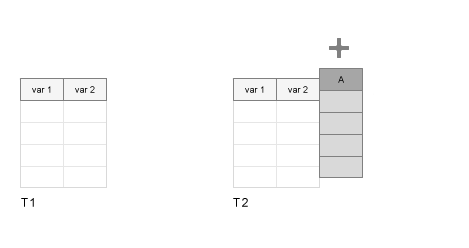

**Figura 5.- **Agregado de caracteristicas de un modelo de datos

%Agregado de valores a tablas ya existentes
auxTable_2 = addvars(auxTable_1,writing);
head(auxTable_2)


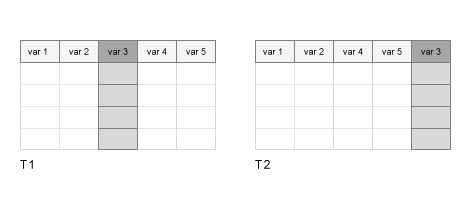

**Figura 6.- **Reordenamiento de caracteristicas de un modelo de datos

%Reordenamiento de caracteristicas de la tabla
auxTable_3 = movevars(auxTable_2,'reading','after','writing');
head(auxTable_3)


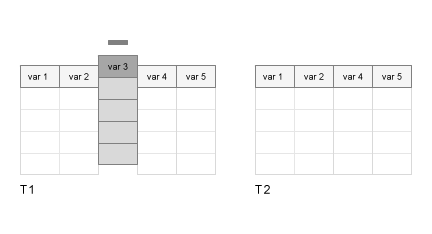

**Figura 7.- **Eliminacion de caracteristicas de un modelo de datos

%Eliminacion de caracteristicas de la tabla
auxTable_4 = removevars(auxTable_2,{'reading'});
head(auxTable_4)

### Filtrado de informacion basado en reglas de valores

%Podemos tambien filtrar los datos por grupos de informacion
%filtrado de la informacion de la tabla auxTable_2 para resultados de datos
%de prueba Matemáticas mayores a 60 pero menores a 80
auxTable = table(gen,math,reading,writing);
head(auxTable)

mathBetween_60_80 = groupfilter(auxTable,"math",@(x) min(x) >= 60 && max(x) <= 80,"math");
head(mathBetween_60_80)
auxMean_Table = groupsummary(mathBetween_60_80,"gen","max")

#### *** Ejercicio ***

Realiza las siguientes operaciones 

- Crea una tabla que contenga las siguientes categorias en este orden: Preparacion de la prueba, genero, Resultado de matemáticas, Resultado de lectura, Resultado de escritura

- Calcula el promedio de los tres valores de las pruebas y coloca el valor al final de las columnas

- Agrupa los resultados por promedio y clasificalos para valores mayores o iguales a 60 pero menores o iguales a 80. ¿Cuantos datos quedaron en total?

- Cual es el promedio general del género masculino que si se preparo para la prueba

- Cual es el promedio general del género femenino que no se preparo para la prueba

- De acuerdo con los datos, ¿Existe una relación directa entre prepararse para la prueba y no prepararse para la prueba?

### Discretizacion de datos en categorias

%Vamos a establecer los siguientes valores de calificaciones en el formato
%americano de calificaciones donde
%Valor | calificacion
%0 59  | F
%60 69 | D
%70 79 | C
%80 89 | B
%90 99 | A
%100   | A+

%Primero estableceremos nuestras nuevas categorias de datos
%etiquetas
calAme = {'F', 'D', 'C', 'B', 'A', 'A+'};

%Limites de calificaciones
limit = [0 59 69 79 89 99 100];
auxVal = dsStudents_3.mathScore; %Solo para guardar el valor
dsStudents_3.mathScore = discretize(dsStudents_3.mathScore, limit, 'categorical', calAme);
summary(dsStudents_3.mathScore)
head(dsStudents_3)
dsStudents_3.mathScore = auxVal; %Regreso el valor original para no entorpecer la BD
head(dsStudents_3)

### Gráficos 

Existen distintas formas de visualizar la información. 

#### Histogramas

Por ejemplo podemos ver la distribucion de datos mediante un histograma

%Muestra el histograma de los datos que pertenecen a un genero masculino o
%femenino 
close all
fig01=figure;
hold on
    histogram(genero,'BarWidth',0.5)
    ylabel("Número de muestras")
    xlabel("Categorias de género")
hold off

#### Swarm

fig02=figure;
hold on
%Esta gráfica nos muestra las categorias y la densidad de valores numéricos
%asociados a cada categoria
    %En el eje X colocaremos las categorias que queremos visualizar
    x=categorical(dsStudents_2.gender);

    %Por su parte, en el eje y colocaremos los valores numéricos que
    %queremos visualizar, en este caso los valores de la prueba de
    %matemáticas
    y=dsStudents_2.mathScore;

    swarmchart(x,y);
hold off


#### Swarm 3D

fig03=figure;
hold on 
    %Podemos realizar una densidad de datos en tres dimensiones de la
    %siguiente manera
    %En el eje x tendremos nuestra primer categoria de datos
    x=categorical(dsStudents_2.gender);

    %En el eje y tendremos nuestra segunda categoria de datos
    y=categorical(dsStudents_2.race_ethnicity);

    %Finalmente en el eje z tendremos la densidad de datos de la prueba de
    %matemáticas

    z=dsStudents_2.mathScore;
    swarmchart3(x,y,z,50,genero,'*')
    
    view([60 40])
    grid minor
    set(gca,'FontSize'       ,20,...
         'MinorGridColor' ,'g',...
        'GridColor'      ,'r',...
        'Xgrid'          ,'on',...
        'Ygrid'          ,'on',...
        'LineWidth'      ,2)
hold off

#### Gráficos de pay

%Primero creamos nuestras categorias
%El nivel de educacion de los padres y el genero del hijo
nivelEducacion=dsStudents_2.parentalLevelOfEducation;
    nivelEducacionyGeneroF = nivelEducacion(dsStudents_2.gender == 'female');
    nivelEducacionyGeneroM = nivelEducacion(dsStudents_2.gender == 'male');
grpCatEtn = categories(dsStudents_2.parentalLevelOfEducation);

fig04=figure;
hold on
    t=tiledlayout(1,2,'TileSpacing','compact');
    ax1 = nexttile;
        pie(nivelEducacionyGeneroF)
        title('Género femenino')
    ax2 = nexttile;
        pie(nivelEducacionyGeneroM)
        title('Género masculino')
    lgd = legend(grpCatEtn);
    lgd.Layout.Tile = 'east';
hold off

#### Scatter(gráfico "x" VS "y")

valMathScore_F = dsStudents_3.mathScore(genero == 'female');
valMathScore_M = dsStudents_3.mathScore(genero == 'male');

valReadingScore_F = dsStudents_3.readingScore(genero == 'female');
valReadingScore_M = dsStudents_3.readingScore(genero == 'male');

valWritingScore_F = dsStudents_3.writingScore(genero == 'female');
valWritingScore_M = dsStudents_3.writingScore(genero == 'male');

fig05=figure;
t=tiledlayout(1,3,'TileSpacing','compact');
ax1 = nexttile;
    hold on
        axis square;
        scatter(valMathScore_F,valWritingScore_F,'bo');
        scatter(valMathScore_M,valWritingScore_M,'r*');
        xlabel('Math Score')
        ylabel('Writing Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off
ax2 = nexttile;
    hold on
        axis square;
        scatter(valMathScore_F,valReadingScore_F,'bo');
        scatter(valMathScore_M,valReadingScore_M,'r*');
        xlabel('Math Score')
        ylabel('Reading Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off    
ax3 = nexttile;
    hold on
        axis square;
        scatter(valReadingScore_F,valWritingScore_F,'bo');
        scatter(valReadingScore_M,valWritingScore_M,'r*');
        xlabel('Reading Score')
        ylabel('Writing Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off   

#### Scatter 3D ("x" Vs "y" Vs "z")

fig06=figure;
hold on
    scatter3(valMathScore_F,valReadingScore_F,valWritingScore_F,'bo');
    scatter3(valMathScore_M,valReadingScore_M,valWritingScore_M,'r*');
    xlabel('Math Score')
    ylabel('Reading Score')
    zlabel('Writing Score')
    view([60 40])
    grid minor
    set(gca,'MinorGridColor' ,'g',...
            'GridColor'      ,'r',...
            'Xgrid'          ,'on',...
            'Ygrid'          ,'on',...
            'LineWidth'      ,2)
hold off     

#### Group Scatter (gráfica que automatiza la distribucion "x" VS "y" dados ciertos grupos

fig07 = figure;
hold on
    gscatter(dsStudents_3.mathScore,dsStudents_3.readingScore,dsStudents_3.gender)
    xlabel('Math Score')
    ylabel('Reading Score')
    grid on
    %grid minor
    set(gca,'Xgrid'          ,'on',...
            'Ygrid'          ,'on',...
            'LineWidth'      ,2)
hold off

#### Matrix Scatter 

xvars = [dsStudents_3.mathScore, dsStudents_3.readingScore, dsStudents_3.writingScore];
yvars = [dsStudents_3.mathScore, dsStudents_3.readingScore, dsStudents_3.writingScore];
colors = [0      0.4470 0.7410;...
          0.8500 0.3250 0.0980;...
          0.4940 0.1840 0.5560];
grp = dsStudents_3.gender;
labels = {'Math', 'Reading', 'Writing'};
fig08 = figure;
hold on
    [h,ax] = gplotmatrix(xvars,yvars,grp,colors,'os*x.');
    for i = 1:3
        xlabel(ax(3,i), labels{i})
        ylabel(ax(i,1), labels{i})
    end
hold off

#### Gráfico de cajas

fig09 = figure;
subplot(1,3,1)
    hold on
        axis square;
        boxplot(dsStudents_2.mathScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Math Score')

    hold off
subplot(1,3,2)
    hold on
        axis square;
        boxplot(dsStudents_2.readingScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Reading Score')

    hold off
subplot(1,3,3)
    hold on
        axis square;
        boxplot(dsStudents_2.writingScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Writing Score')
    hold off    

#### Gráfico de coordenadas paralelas

%Datos categoricos
gen = dsStudents_2.gender;
race = dsStudents_2.race_ethnicity;

%Datos numéricos
math = dsStudents_2.mathScore;
reading = dsStudents_2.readingScore;
writing = dsStudents_2.writingScore;

%Tabla auxiliar
auxTable = table(gen,math,reading,writing);
%auxGrpTable = 
fig10 = figure;
hold on
    parallelcoords(xvars,"Group",grp,"Quantile",0.25)
hold off


#### *** Ejercicio ***

Realiza las siguientes operaciones

- Clasifica los datos por raza y por genero

- Muestra una figura de histograma basado en esta clasificación: tres gráficas (pruebas de matemáticas, lectura y escritura) con dos categorias del histograma [femenino y masculino]

- Muestra una figura de histograma basado en esta clasificiación: cinco gráficas con tres categorias (pruebas de matemáticas, de lectura y de escritura)

- Muestra una figura de "Swarm 3D" basado en esta clasificación: tres gráficas con cinco categorias en x (los cinco grupos de razas) seis categorias en y (correspondientes a los grados de educacion de los padres) y dependiendo de la prueba realizada los datos de matemáticas, lectura y escritura

- Muestra en una figura de pay cual es el porcentaje de genero que tuvo un curso de preparacion y cuantos de estos obtuvieron una nota promedio aprobatoria

- Muestra en una figura de gráficos de caja, cual es la distribucion de aquellos que desayunaron vs aquellos que obtuvieron una nota promedio aprobatoria